# Kotal & Al

Instead of looking for peaks on the orig_sig, we look for them in the detrended signal. We keep a minimum peak height in the slips to be negative to keep FPs low.

Initialize:

close all;
clear all;
load("a5c3ecg.mat") % visible bradycardia
load("G011ecg.mat") % Heavy bias, brady -> 5 missed beats
load("A1ecg.mat") % Faint
load("a2f1ecg.mat") % Some Missed beats -> Tweak
fs = 1000;

Choose the signal here:

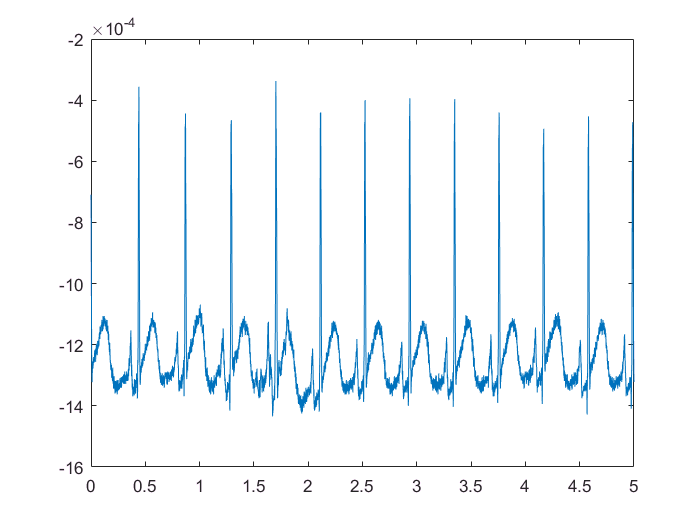

sig = transpose(G011ecg);
orig_sig = sig;
time = 0:(1/fs):((length(sig)-1)/fs);
plot(time,sig);

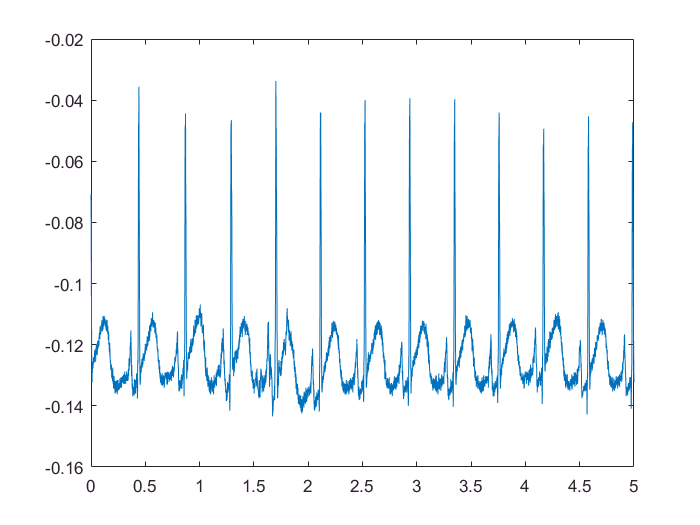

sig = sig.*100;
plot(time,sig);

Every second of the ECG signal was normalized by the standard deviation of the signal in that second

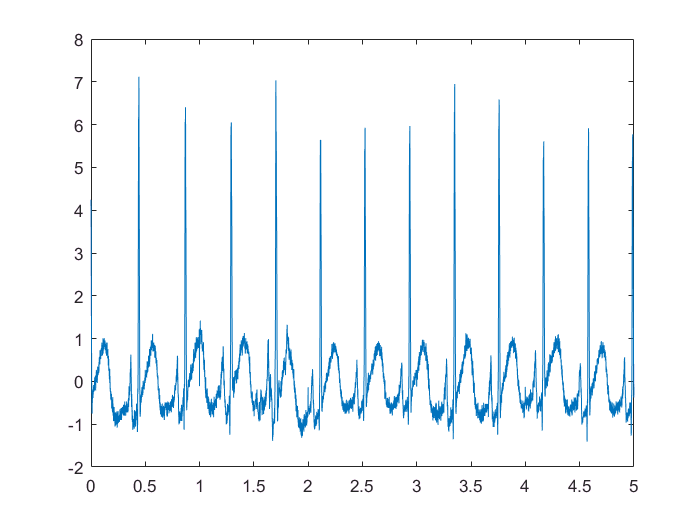

numSecs = floor(length(sig) / fs);

for i = 0:numSecs-1
    currSec = sig(1+i*fs:(i+1)*fs-1);
    M = mean(currSec);
    S = std(currSec);
    normalizedSec = arrayfun(@(a) (a - M)/ S, currSec);
    sig(1+i*fs:(i+1)*fs-1) = normalizedSec;
end

plot(time,sig);

Remove NaNs:

sig(isnan(sig)) = 0;
plot(time,sig);

ECG was detrended using a 120-ms smoothing filter with a zero-phase distortion.

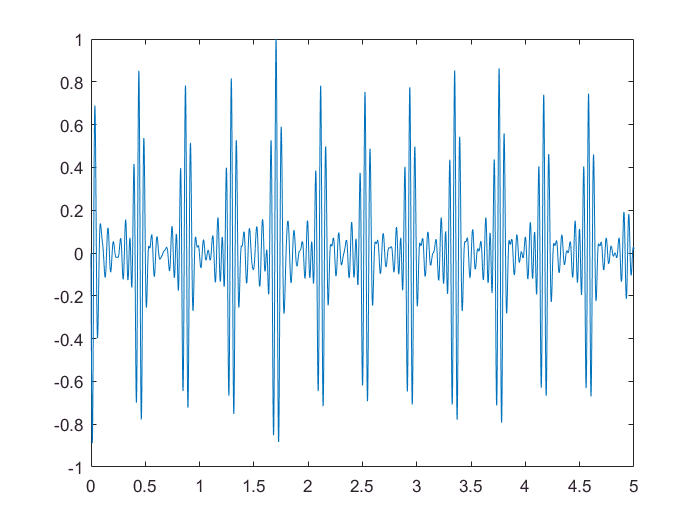

detrended = sig;
sig = preprocessing(sig, fs);
ecg_h = sig;
plot(time,sig);

Difference between successive samples of the signal – equivalent to a highpass filter – was calculated.

sig = diff(sig);
sig(length(sig)+1)=0;

The signal is then rectified:

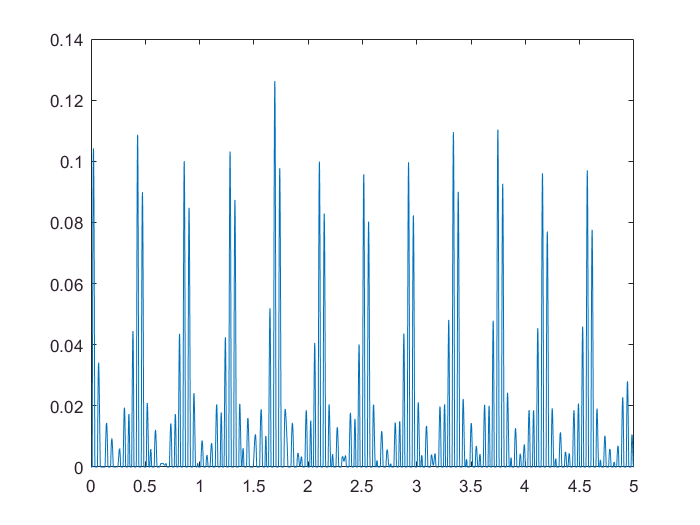

idx = sig < 0;
sig(idx) = 0;
plot(time,sig);

A 150 ms running average was calculated for the rectified data.

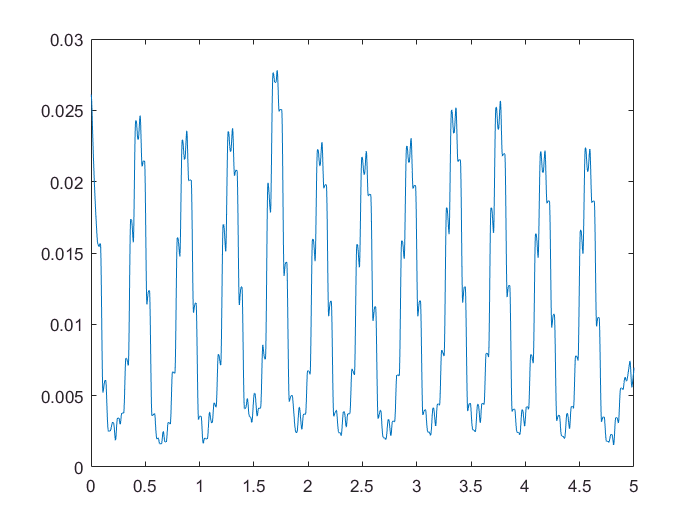

timeWind = 150; %In ms
sig = movmean(sig, timeWind);
movingAverage = sig;
plot(time,sig);

Moving window integration

h = ones (1 ,31)/31; % Make impulse response
Delay = 31; % Delay in samples
% Apply filter
x6 = conv (sig ,h);
N = length(x6) - Delay;
x6 = x6 (Delay+[1: N]);
if length(x6) < length(sig)
    x6(length(x6):length(sig)) = sig(length(x6):length(sig));
end
%sig=x6;
plot(time,sig);

Hilbert Transform

transformH = hilbert(sig);

Find the instantaneous angle:

angleRads = angle(transformH + sig);
plot(time,angleRads);

Find the peaks:

[pks,locs] = findpeaks(-angleRads,'MinPeakDistance',250, 'MinPeakHeight',0);
hold on;
plot(time(locs),angleRads(locs),'rv','MarkerFaceColor','r')
plot(time,angleRads);

Find R-Peaks:

left = locs;
for i=1:length(left)-1
 [R_value(i), R_loc(i)] = max( detrended(left(i):left(i+1)) );
 R_loc(i) = R_loc(i)-1+left(i); % add offset
end

hold on;
plot (time,orig_sig);
plot(time(R_loc),orig_sig(R_loc),'rv','MarkerFaceColor','r');

Find the Heart Rate:

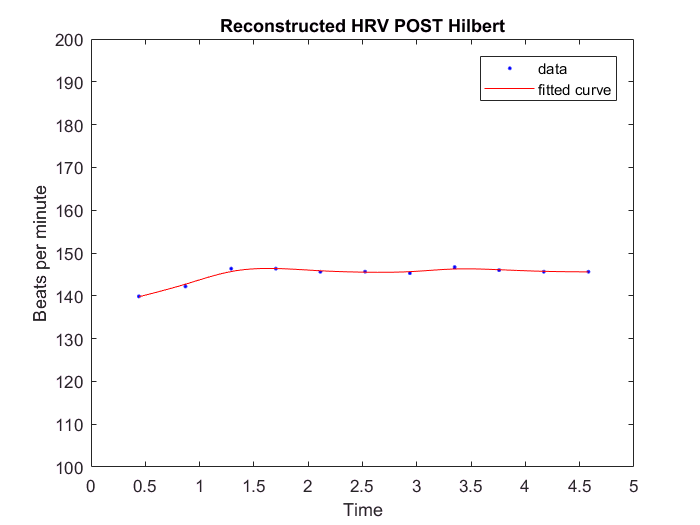

interval = diff(R_loc); % Period
interval(length(interval)+1) = interval(length(interval)); % Adding one last index
periodMs = interval;
interval = interval./fs;
interval = interval.^-1;
interval = interval.*60; % To get BPM
interval(isinf(interval))=0;

f=fit(transpose(time(R_loc)),transpose(interval),'smoothingspline');
plot(f,time(R_loc),interval);
title("Reconstructed HRV POST Hilbert");
ylabel("Beats per minute");
xlabel("Time");
ylim([100 200]);

We measure the velocity of change of the heart rate:

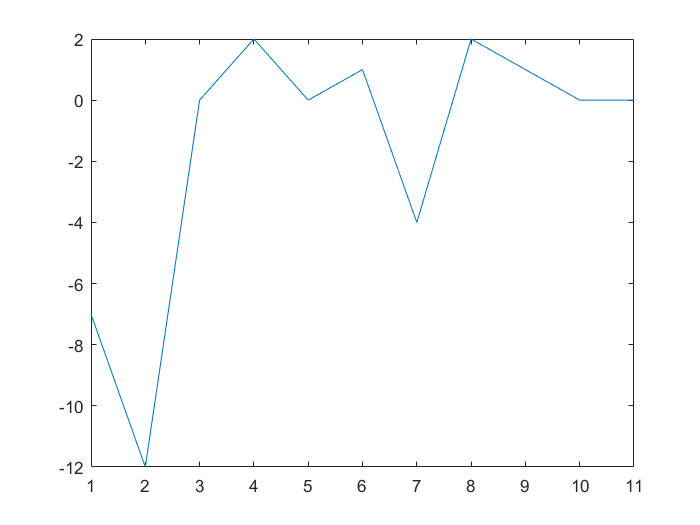

vel = diff(periodMs);
vel(length(vel)+1)=0;
figure;
plot(1:length(vel),vel);